# Linear Algebra Project 1 - Q3 - 810101477

## Introduction

This live script implements the training of a single-layer perceptron using Newton's method, as described in the problem. We will cover data generation, analytical derivations of the gradient and Hessian, implementation of the training loop, and evaluation of the results.

**A Note on the Loss Function**

The problem specifies the loss function as $L = \sum (y_i - \hat{y}_i)$. This function is not continuously differentiable and its gradient is piecewise constant, which makes it unsuitable for second-order optimization methods like Newton's method. Standard practice for such regression or classification tasks is to use the **Sum of Squared Errors (SSE)** loss function, $L = \sum (y_i - \hat{y}_i)^2$. The request to calculate the Hessian matrix strongly implies that a twice-differentiable loss function was intended. Therefore, all subsequent derivations and implementations will use the SSE loss function.

**Setup: Data Generation and Splitting**

First, we generate a synthetic dataset as specified. We create `N=100` data points with `n=2` features. The data consists of two linearly separable classes with labels 0 and 1, which satisfies the condition that the target values `y` are in the range `[0, 1]`.

%% Part A: Data Generation and Splitting
clear; clc; close all;

% For reproducibility
rng(42); 

% --- Data Generation ---
N = 100; % Total number of data points
n = 2;   % Number of features

% Generate two distinct classes of data
class1_mean = [2, 2];
class2_mean = [-2, -2];
covariance = eye(n);
num_per_class = N / 2;

X1 = mvnrnd(class1_mean, covariance, num_per_class);
Y1 = ones(num_per_class, 1);

X2 = mvnrnd(class2_mean, covariance, num_per_class);
Y2 = zeros(num_per_class, 1);

% Combine and shuffle the data
X = [X1; X2];
Y = [Y1; Y2];
shuffled_indices = randperm(N);
X = X(shuffled_indices, :);
Y = Y(shuffled_indices, :);

% --- Data Splitting (80% train, 20% test) ---
cv = cvpartition(N, 'HoldOut', 0.2);
idxTrain = training(cv);
idxTest = test(cv);

XTrain = X(idxTrain, :);
YTrain = Y(idxTrain, :);
XTest = X(idxTest, :);
YTest = Y(idxTest, :);

fprintf('Data generated and split successfully.\n');

Data generated and split successfully.


fprintf('Training set size: %d\n', size(XTrain, 1));

Training set size: 80


fprintf('Test set size: %d\n', size(XTest, 1));

Test set size: 20


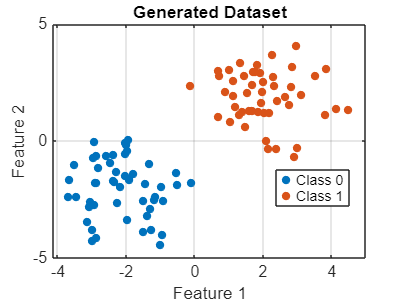


% Visualize the dataset
figure;
gscatter(X(:,1), X(:,2), Y);
title('Generated Dataset');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Class 0', 'Class 1');
grid on;

**B - Analytical Gradient**

For a single data point $(x_i, y_i)$, the loss is $L_i = (y_i - \hat{y}_i)^2$. The prediction is $\hat{y}_i = \sigma(z_i)$, where $z_i = W^T x_i + b$ and $\sigma(z) = \frac{1}{1+e^{-z}}$.

To simplify notation, we combine the weights and bias into a single parameter vector  and augment the input vector as $x_{a,i} = B x_i  1 B$. Now, $z_i = \alpha^T x_{a,i}$.

The gradient of the loss `L_i` with respect to `\alpha` is found using the chain rule:


$$\nabla_{\alpha}L_i = \frac{\partial L_i}{\partial \hat{y}_i} \frac{\partial \hat{y}_i}{\partial z_i} \frac{\partial z_i}{\partial \alpha}$$


The individual terms are:


$$\frac{\partial L_i}{\partial \hat{y}_i} = -2(y_i - \hat{y}_i)$$



$$\frac{\partial \hat{y}_i}{\partial z_i} = \sigma'(z_i) = \sigma(z_i)(1-\sigma(z_i))$$



$$\frac{\partial z_i}{\partial \alpha} = x_{a,i}$$


Combining these gives the gradient for a single point:


$$\nabla_{\alpha}L_i = -2(y_i - \hat{y}_i)\sigma'(z_i)x_{a,i}
$$


The total gradient for the entire dataset is the sum of these individual gradients: $\nabla L = \sum_i \nabla_{\alpha}L_i.
$

**C - Analytical Hessian**

The Hessian matrix is the matrix of second derivatives, $\nabla_{\alpha}^2 L_i.$ We differentiate the gradient with respect to $ \alpha^T$:


$$\nabla_{\alpha}^2 L_i = \frac{\partial}{\partial \alpha^T} (\nabla_{\alpha} L_i) = \frac{\partial}{\partial \alpha^T} [-2(y_i - \hat{y}_i)\sigma'(z_i)x_{a,i}]$$


Using the chain rule again $(\frac{\partial}{\partial \alpha^T} = \frac{\partial z_i}{\partial \alpha^T} \frac{d}{d z_i} = x_{a,i}^T \frac{d}{d z_i})$, we get:


$$\nabla_{\alpha}^2 L_i = \left( \frac{d}{dz_i}[-2(y_i - \sigma(z_i))\sigma'(z_i)] \right) x_{a,i} x_{a,i}^T$$


The derivative term is:


$$\frac{d}{dz_i}[-2(y_i - \sigma(z_i))\sigma'(z_i)] = -2[-\sigma'(z_i)^2 + (y_i - \sigma(z_i))\sigma''(z_i)] = 2[\sigma'(z_i)^2 - (y_i - \sigma(z_i))\sigma''(z_i)]$$


where $\sigma''(z_i) = \sigma'(z_i)(1-2\sigma(z_i))$. So, the Hessian for a single data point is:


$$\nabla_{\alpha}^2 L_i = 2[\sigma'(z_i)^2 - (y_i - \hat{y}_i)\sigma''(z_i)] x_{a,i}x_{a,i}^T$$


The total Hessian for the dataset is the sum of individual Hessians: $\nabla^2 L = \sum_i \nabla_{\alpha}^2 L_i.
$

**D & E - Newton's Method Update and Training**

The Newton update rule for the parameters `\alpha` is:


$$\alpha_{new} = \alpha_{old} - (\nabla^2 L)^{-1} (\nabla L)
$$


We implement a loop that repeatedly calculates the total gradient and Hessian over the training data, updates the parameters, and checks for convergence. The loop stops when the Newton decrement, $\lambda = 0.5(\nabla L)^{T}(\nabla^2 L)^{-1}(\nabla L)$, falls below a small threshold $\epsilon$, or when the maximum number of iterations is reached.

%% Part D & E: Newton's Method Implementation
% --- Augment Data with a bias term ---
XTrain_aug = [XTrain, ones(size(XTrain, 1), 1)];
XTest_aug = [XTest, ones(size(XTest, 1), 1)];

% --- Helper Functions ---
sigmoid = @(z) 1 ./ (1 + exp(-z));
sigmoid_prime = @(z) sigmoid(z) .* (1 - sigmoid(z));
sigmoid_prime2 = @(z) sigmoid_prime(z) .* (1 - 2*sigmoid(z));

% --- Initialization ---
alpha = randn(n + 1, 1) * 0.1; % Initial parameters [W; b]
max_iter = 1000;
epsilon = 1e-4; % Stopping criterion threshold
train_loss_history = zeros(max_iter, 1);
test_loss_history = zeros(max_iter, 1);
num_train_samples = size(XTrain_aug, 1);

fprintf('\nStarting Newton''s method training...\n');


Starting Newton's method training...



% --- Training Loop ---
for k = 1:max_iter
    % Initialize total gradient and Hessian for this epoch
    total_grad = zeros(n + 1, 1);
    total_hessian = zeros(n + 1, n + 1);

    % --- Calculate Gradient and Hessian over the entire training set ---
    for i = 1:num_train_samples
        xi = XTrain_aug(i, :)';
        yi = YTrain(i);
        
        zi = alpha' * xi;
        yi_hat = sigmoid(zi);
        
        s_p = sigmoid_prime(zi);
        s_p2 = sigmoid_prime2(zi);
        
        % Gradient for one sample
        grad_i = -2 * (yi - yi_hat) * s_p * xi;
        
        % Hessian for one sample
        d2L_dz2 = 2 * (s_p^2 - (yi - yi_hat) * s_p2);
        hess_i = d2L_dz2 * (xi * xi');
        
        % Accumulate
        total_grad = total_grad + grad_i;
        total_hessian = total_hessian + hess_i;
    end
    
    % --- Newton Update Step ---
    % Add regularization to prevent singularity
    H_reg = total_hessian + 1e-6 * eye(n + 1);
    
    % Solve for the step: H * step = grad
    step = H_reg \ total_grad;
    
    % Update parameters
    alpha = alpha - step;
    
    % --- Calculate and Store Loss ---
    % Training loss
    Yhat_train = sigmoid(XTrain_aug * alpha);
    train_loss_history(k) = sum((YTrain - Yhat_train).^2);
    
    % Test loss
    Yhat_test = sigmoid(XTest_aug * alpha);
    test_loss_history(k) = sum((YTest - Yhat_test).^2);
    
    % --- Check Stopping Criterion ---
    lambda = 0.5 * total_grad' * step;
    if mod(k, 5) == 0
        fprintf('Iter: %d, Train Loss: %.4f, Test Loss: %.4f, Lambda: %.6f\n', k, train_loss_history(k), test_loss_history(k), lambda);
    end
    
    if abs(lambda) < epsilon
        fprintf('\nConvergence reached at iteration %d.\n', k);
        break;
    end
end

Iter: 5, Train Loss: 0.0684, Test Loss: 0.0080, Lambda: 0.087132
Iter: 10, Train Loss: 0.0005, Test Loss: 0.0000, Lambda: 0.000644



Convergence reached at iteration 12.



% Trim unused history arrays
train_loss_history(k+1:end) = [];
test_loss_history(k+1:end) = [];

**F - Report and Plot Loss**

After training, we report the final loss on both the training and test sets. We also plot the loss curves to visualize the training process. Finally, we plot the decision boundary learned by the model on the test data.

%% Part F: Report Loss and Plot Results

final_train_loss = train_loss_history(end);
final_test_loss = test_loss_history(end);

fprintf('\n--- Training Finished ---\n');


--- Training Finished ---


fprintf('Final Training Loss (SSE): %.4f\n', final_train_loss);

Final Training Loss (SSE): 0.0001


fprintf('Final Test Loss (SSE): %.4f\n', final_test_loss);

Final Test Loss (SSE): 0.0000


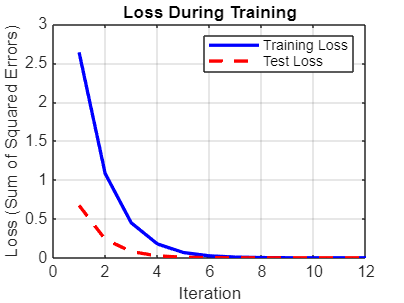


% --- Plot Loss History ---
figure;
plot(1:k, train_loss_history, 'b-', 'LineWidth', 2);
hold on;
plot(1:k, test_loss_history, 'r--', 'LineWidth', 2);
title('Loss During Training');
xlabel('Iteration');
ylabel('Loss (Sum of Squared Errors)');
legend('Training Loss', 'Test Loss');
grid on;

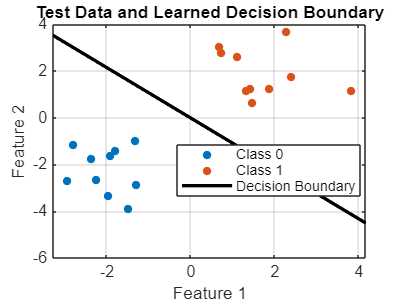


% --- Plot Decision Boundary ---
figure;
gscatter(XTest(:,1), XTest(:,2), YTest);
hold on;

% The decision boundary is where z=0, so W'x + b = 0
% alpha(1)*x1 + alpha(2)*x2 + alpha(3) = 0
% x2 = (-alpha(1)*x1 - alpha(3)) / alpha(2)
x1_vals = xlim;
x2_vals = (-alpha(1)*x1_vals - alpha(3)) / alpha(2);
plot(x1_vals, x2_vals, 'k-', 'LineWidth', 2);
title('Test Data and Learned Decision Boundary');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Class 0', 'Class 1', 'Decision Boundary');
grid on;

**G - Bonus: Two-Layer Network**

For the network defined as $\hat{y}_i = W_2\sigma(W_1^T x_i + b_1) + b_2$, the process of finding the gradient and Hessian becomes significantly more complex. Let's assume a single hidden neuron for simplicity.

The parameters are$ \alpha = [W_{11}, W_{12}, b_1, W_2, b_2]^T$. The forward pass is: $z_1 = W_1^T x_i + b_1, h = \sigma(z_1), \hat{y}_i = W_2 h + b_2.$ The loss for one point is $L_i = (y_i - \hat{y}_i)^2.$

**Gradient Derivations (Part B repeated):**Using the chain rule, the gradients are:

- 
$$\frac{\partial L_i}{\partial b_2} = \frac{\partial L_i}{\partial \hat{y}_i} \frac{\partial \hat{y}_i}{\partial b_2} = -2(y_i - \hat{y}_i) \cdot 1$$


- 
$$\frac{\partial L_i}{\partial W_2} = \frac{\partial L_i}{\partial \hat{y}_i} \frac{\partial \hat{y}_i}{\partial W_2} = -2(y_i - \hat{y}_i) \cdot h$$


- 
$$\frac{\partial L_i}{\partial b_1} = \frac{\partial L_i}{\partial \hat{y}_i} \frac{\partial \hat{y}_i}{\partial h} \frac{\partial h}{\partial z_1} \frac{\partial z_1}{\partial b_1} = -2(y_i - \hat{y}_i) \cdot W_2 \cdot \sigma'(z_1) \cdot 1$$


- 
$$\frac{\partial L_i}{\partial W_1} = \frac{\partial L_i}{\partial \hat{y}_i} \frac{\partial \hat{y}_i}{\partial h} \frac{\partial h}{\partial z_1} \frac{\partial z_1}{\partial W_1} = -2(y_i - \hat{y}_i) \cdot W_2 \cdot \sigma'(z_1) \cdot x_i$$


**Hessian and Update (Parts C-F repeated):**To repeat the remaining parts, one would have to:

- **Analytically derive the **`5 \times 5`** Hessian matrix.** This involves taking the second partial derivatives of the loss with respect to all pairs of parameters (e.g., $\frac{\partial^2 L_i}{\partial W_2^2}, \frac{\partial^2 L_i}{\partial W_2 \partial b_1}$, etc.). This is a lengthy and error-prone process.

- **Implement the new forward pass.**

- **Implement the calculation of the **$5 \times 1$** gradient vector and the **$5 \times 5$** Hessian matrix** inside the training loop based on the new derivations.

- **Run the Newton's method training loop** with the new 5-dimensional parameter vector.

- **Compare the final test loss** to the one obtained with the single-layer network.

A two-layer network has greater expressive power and could potentially achieve a lower test loss, especially if the data were not linearly separable. However, for this linearly separable dataset, the improvement may be marginal and comes at the cost of a much more complex and computationally expensive training procedure (calculating and inverting a $5 \times 5$ Hessian at each step for each data point vs. a $3 \times 3$ one). The risk of overfitting also increases.